k = 18

k = 18


a = -pi/4;
b = pi/4;
L = b - a;

c = k;
nu = .9;
Nx = 11;
h = L ./ (Nx - 1);
T = 4;
tau = nu*h/c;
Nt = ceil(T/tau) + 1;

x = linspace(a, b, Nx);
u_0 = 5 + (x + pi/4) - (x + pi/4).^2/pi;
u_tau = u_0;

U_next = eye(Nx);
U_now = (2-2*nu^2)*eye(Nx) + ...
    diag(nu^2 * ones(Nx-1, 1), 1) + ...
    diag(nu^2 * ones(Nx-1, 1),-1);
U_prev = -U_next;


Border conditions

U_now(1, :) = 0;
U_now(end, :) = 0;
U_prev(1, :) = 0;
U_prev(end, :) = 0;
U_next(end, end-1) = -1;

Integration

U = zeros(Nt, Nx);
U(1:2, :) = [u_0; u_tau];

for n = 3 : Nt
    rightPart = U_now * U(n-1, :).' + U_prev * U(n-2, :).';
    rightPart(1) = 5;
    rightPart(end) = 0;
    U(n, :) = U_next \ rightPart;
end

Visualisation

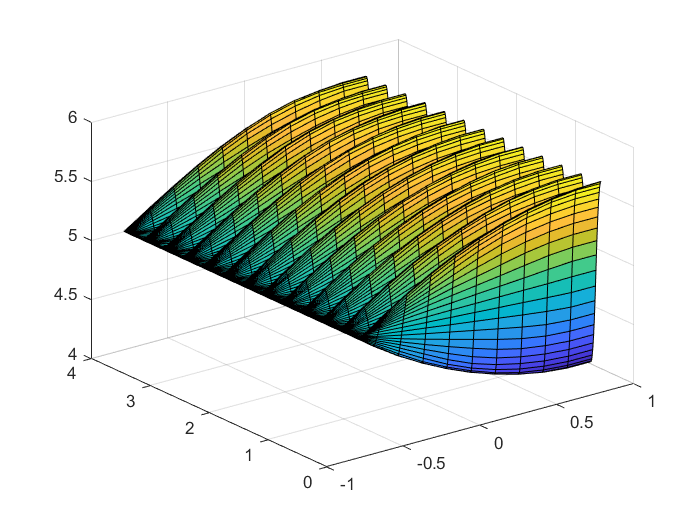

figure
[t_mesh, x_mesh] = meshgrid(x, linspace(0, T, Nt));
surf(t_mesh, x_mesh, U);